% In diesem Skript wird der Einfluss des kapazitiven Belages, verursacht
% durch die 2 km Kabel zwischen Zürich Museumsstrasse und UW Zürich, abgeschätzt.
% Der Widerstandsbelag wird bei den Berechnungen vernachlässigt.

Import_measurements2;

US = 1.5002e+04

Z = 1.0998e+02 - 7.5334e+00i

%Import_measurements2;
Up = 15000; % Up am Fahrzeug sollte 15 kV entsprechen (da an der Messstelle nach dem Kabel
% die Spannung höher ist)

XL1 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
XL2 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
Xc = 1/(j* 2 * pi * 16.67 * 6 * 10^(-6))*2; % Kapazitätsbelag
R = 0.141*2; % Widerstandsbelag 


% Hochrechnung der simulierten Leistung (8 min Mittelwerte)
Correction = array2table(P_totMean');

Unrecognized function or variable 'P_totMean'.

Correction.Properties.VariableNames = "PAlt";
Correction.Rw = Up^2./(P_totMean*1000)'; % Wellenwiderstand am Fahrzeug
Correction.Z = 1./(1./(Correction.Rw + XL2) + 1/Xc) + XL1; % Gesamtimpedanz
Correction.PNeu = Correction.PAlt./cos(angle(Correction.Z)); % neue Leistung

% Berechnung der korrigierten Messwerte
for n = 1:height(Meas)
    Meas.Rw(n) = ((Meas.U8minMittelkV(n) * 1000)^2)/(Meas.P8minMittelMW(n) * 10^(6));
    Meas.Z(n) = 1/(1/(Meas.Rw(n) + XL2) + 1/Xc) + XL1;
    Meas.PCorr(n) = Meas.P8minMittelMW(n) * cos(angle(Meas.Z(n)));
end


## Berechnung 8 min Mittelwert

       
n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totDimMean.P_totSim(n,1) = mean(P_totDim.P_totSim(1:i));
    else
        P_totDimMean.P_totSim(n,1) = mean(P_totDim.P_totSim(i-4800:i));
    end
    n = n + 1;
end




## Versuch für das Main Script:

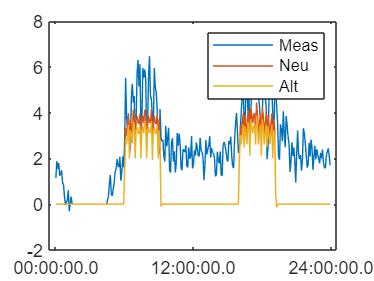

Up = 15000; % Up am Fahrzeug sollte 15 kV entsprechen (da an der Messstelle nach dem Kabel
% die Spannung höher ist)

time2 = seconds(0:300:86400-300);
time2.Format = 'hh:mm:ss.S';

XL1 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
XL2 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
Xc = 1/(j* 2 * pi * 16.67 * 6 * 10^(-6))*2; % Kapazitätsbelag
R = 0.094; % Widerstandsbelag 

% Rw = sqrt(1*10^(-3)/(6*10^(-6)));
% 
% P_totCorr = P_totDimMean.P_totSim;
% P_totCorr = array2table(P_totCorr);
% P_totCorr.Properties.VariableNames = "PAlt";
% P_totCorr.Rw = Up^2./(P_totCorr.PAlt*1000);
% P_totCorr.Z(:) = 1/(1/(Rw + XL2 + R) + 1/Xc) + XL1 + R;
% P_totCorr.PNeu = P_totCorr.PAlt./cos(angle(P_totCorr.Z));
% 
% P_totCorr.Diff = P_totCorr.PNeu - P_totCorr.PAlt;

P_totCorr = P_totDimMean.P_totSim;
P_totCorr = array2table(P_totCorr);
P_totCorr.Properties.VariableNames = "PAlt";
P_totCorr.Rw = Up^2./(P_totCorr.PAlt*1000);
P_totCorr.Z(:) = 1/(1/(XL2 + R) + 1/Xc) + XL1 + R;
P_totCorr.PNeu = P_totCorr.PAlt./cos(angle(P_totCorr.Z));

P_totCorr.Diff = P_totCorr.PNeu - P_totCorr.PAlt;

figure(1)
plot(time2, Meas.P8minMittelMW(1:length(time2)))
hold on
plot(time2, P_totCorr.PNeu/1000)
plot(time2, P_totCorr.PAlt/1000)
legend('Meas', 'Neu', 'Alt')
hold off

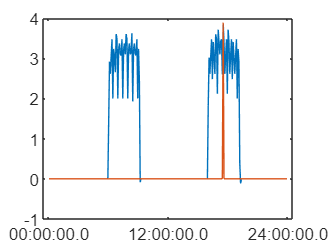

Up = 15000; % Up am Fahrzeug sollte 15 kV entsprechen (da an der Messstelle nach dem Kabel
% die Spannung höher ist)

XL1 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
XL2 = j * 2 * pi * 16.67 * 0.5 * 10^(-3); % halber Induktivitätsbelag
Xc = 1/(j* 2 * pi * 16.67 * 6 * 10^(-6))*2; % Kapazitätsbelag
R = 0.141*2; % Widerstandsbelag 

% Hochrechnung der simulierten Leistung (8 min Mittelwerte)
P_totDimMean.P_totSim(:,2) = (Up^2/1000)/(P_totDimMean.P_totSim(:,1)); % WellenWiderstände
P_totDimMean.P_totSim(:,3) = 1./(1./(P_totDimMean.P_totSim(:,2) + XL2) + 1/Xc) + XL1; % Impedanz
P_totDimMean.P_totSim(:,4) = P_totDimMean.P_totSim(:,1).*cos(angle(P_totDimMean.P_totSim(:,3))); % neue Leistung


figure
plot(time2, P_totDimMean.P_totSim(:,1)/1000)
hold on
plot(time2, P_totDimMean.P_totSim(:,4)/1000)

Z = sqrt((XL1 + XL2 + R)/Xc)

Z = 0.0056 + 0.0080i

cos(angle(Z))

ans = 0.5709






Meas.U8minMittelkV(1) * Meas.I8minMittelA(1)/1000

ans = 2.1243


Meas.P8minMittelMW(99) * cos(angle(0.0078 + 0.0113i))

ans = 3.6698


Rw = (Meas.U8minMittelkV(83)/1000)^2/(Meas.P8minMittelMW(83)/10^6)

Rw = 49.8550


Z = 1/(1/(Rw + XL2 + R/2) + 1/(Xc+R/2)) + XL1

Z = 49.9853 - 0.6805i


cos(angle(Z))

ans = 0.9999


P = Meas.P8minMittelMW(83) * cos(angle(Z))

P = 4.7196